Prepares the dataset and saves to a .mat file

% load all of the dataset
images = imageDatastore("data/extracted_images/**/*_*.jpg", "FileExtensions", ".jpg","LabelSource","foldernames")

images =   ImageDatastore with properties:

                       Files: {
                              ' ...\Classes\Fall 2020\QEA\QEA-Project1\data\extracted_images\(\(_1000.jpg';
                              ' ...\Fall 2020\QEA\QEA-Project1\data\extracted_images\(\(_100003.jpg';
                              ' ...\Fall 2020\QEA\QEA-Project1\data\extracted_images\(\(_100042.jpg'
                               ... and 54867 more
                              }
                     Folders: {
                              'C:\Classes\Fall 2020\QEA\QEA-Project1\data\extracted_images\(';
                              'C:\Classes\Fall 2020\QEA\QEA-Project1\data\extracted_images\)';
                              'C:\Classes\Fall 2020\QEA\QEA-Project1\data\extracted_images\+'
                               ... and 16 more
                              }
                      Labels: [(; (; ( ... an

% breakdown by label
totals = images.countEachLabel

totals = 19×2 table
    Label    Count
    _____    _____

      (      4387 
      )      4381 
      +      6680 
      -      8607 
      0      2052 
      1      7565 
      2      7200 
      3      2962 
      4      1980 
      5      1138 
      6       945 
      7       885 
      8       871 
      9       884 
      =      3879 
      X       320 


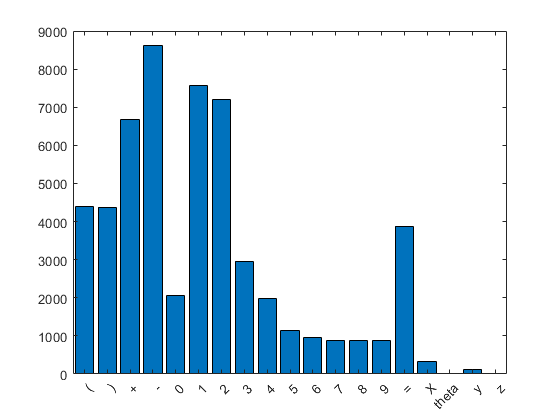

bar(categorical(totals{:,"Label"}), totals{:,"Count"});

% split into training and testing images and read
[train, test] = splitEachLabel(images, 0.7);
train_labels = train.Labels;
test_labels = test.Labels;
train_images = train.readall();
test_images = test.readall();

% save to .mat
save("train.mat", "train_images", "train_labels");
save("test.mat", "test_images", "test_labels");